# Réponses indicielles et diagrammes de Bode en utilisant différentes approximations

## Paramètres

Tu = 16.5;
Tg = 172.5;
disp(Tu/Tg)

    0.0957



a = 0.115;
Kp = 0.395;
t1 = 68;
t2 = 92;

## Broida

s = tf('s');
T = Tg;
theta = Tu;

f = (Kp/(T*s+1))*exp(-theta*s);

## Broida 2

s = tf('s');
T = 5.5*(t2-t1);
theta = 2.8*t1-1.8*t2;
disp(T)

   132



disp(theta)

   24.8000



g = (Kp/(T*s+1))*exp(-theta*s);

## Van der Grinten

s = tf('s');
%T1 = Tg*(1-(3*a*exp(1))/(1+a*exp(1)));
T1 = 0;
T2 = Tg*((1-a*exp(1))/(1+a*exp(1)));
disp(T2)

   90.3366



theta = Tu-((T1*T2)/(T1+3*T2));
disp(theta)

   16.5000



h = (Kp/((T1*s+1)*(T2*s+1)))*exp(-theta*s);

## Strejc

n = 1;
T = Tg/1;
Tuth = 0*Tg;
theta = Tu-Tuth;
disp(theta)

   16.5000



disp(T)

  172.5000



i = (Kp/((T*s+1)^n))*exp(-theta*s);

b = plot(t,(y-y(2,1))/40);
hold on
steps = stepplot(f,g,h,i)


steps =

	resppack.timeplot



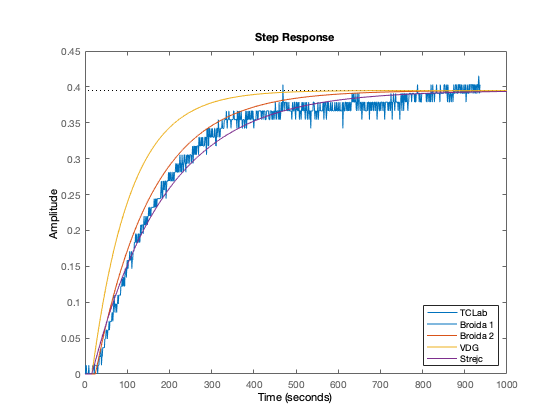

legend({'TCLab','Broida 1','Broida 2','VDG','Strejc'}, 'Location','southeast','NumColumns',1)
axis([0 1000 0 0.45])
hold off


bodes = bodeplot(f,g,h,i)


bodes =

	resppack.bodeplot



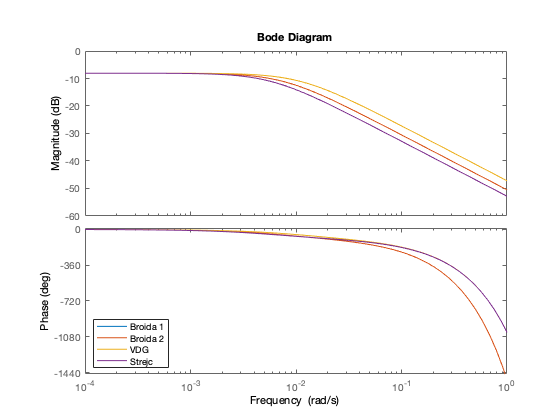

legend({'Broida 1','Broida 2','VDG','Strejc'}, 'Location','southwest','NumColumns',1)